clc
clear all


T = readtable('srca.xlsx','Sheet','endpoint');
%%Sr/Ca monthly interpolation for 1671.583 - 2007.583
T.SrCa(T.SrCa == 0) = nan;
T.RSD(T.RSD == 0) = nan;
Year = flip(fillmissing(T.Winters,"linear","SamplePoints",T.Depth)); %fill gap and flip
SrCa = flip(T.SrCa); %flip first to match age model
SrCaerror = flip(T.RSD).*SrCa/100;
[SrCa,~] = fillmissing(SrCa,"linear","SamplePoints",Year); %fill gap 
[SrCaerror,~] = fillmissing(SrCaerror,"linear","SamplePoints",Year);
yearsst = [(1671+1/12*7):1/12:(2007+1/12*7)]'; %1671.583 - 2007.583
srcamonthly = interp1(Year,SrCa,yearsst,'linear',"extrap");
srcaerrorindividual = interp1(Year,SrCaerror,yearsst,'linear',"extrap");
srcaerrlongterm = 0.006;
srcaerrormonthly = sqrt(srcaerrorindividual.^2+srcaerrlongterm^2);

TSSTA = readtable('SSTA.xlsx');

Date = TSSTA.Date;
TSSTA.Mon = categorical(TSSTA.Mon);
ERSSTA=TSSTA.ERSSTv5;
HadISSTA=TSSTA.HadISST1;
HadSSTA=TSSTA.HadSST4;
HadSSTA_err = TSSTA.HadSST4error;
OISSTA = TSSTA.OISSTv2;
OISSTA_err = TSSTA.OISSTv2error;
SrCaA=TSSTA.SrCa;
SSTA = SrCaA/-0.084;
SD_a1 = (1/-0.061).*srcaerrormonthly;
SD_a2 = - ((SrCaA./((-0.061)^2))*0.02);
SSTA_Err = sqrt(SD_a1.^2+SD_a2.^2);

gap = (4:12:4024)';
yr = (1672:2006)';

ASSTA = zeros(size(yr,1),1);
for i=1:size(yr,1);
    t=SSTA(gap(i):(gap(i+1)-1));
    ASSTA(i) = mean(t,'omitnan');
i=i+1;
end

ASSTA_Err = zeros(size(yr,1),1);
for i=1:size(yr,1);
    t=SSTA_Err(gap(i):(gap(i+1)-1));
    ASSTA_Err(i) = rms(t,'omitnan');
i=i+1;
end

AERSSTA = zeros(size(yr,1),1);
for i=1:size(yr,1);
    t=ERSSTA(gap(i):(gap(i+1)-1));
    AERSSTA(i) = mean(t,'omitnan');
i=i+1;
end

AHadISSTA = zeros(size(yr,1),1);
for i=1:size(yr,1);
    t=HadISSTA(gap(i):(gap(i+1)-1));
    AHadISSTA(i) = mean(t,'omitnan');
i=i+1;
end

AHadSSTA = zeros(size(yr,1),1);
for i=1:size(yr,1);
    t=HadSSTA(gap(i):(gap(i+1)-1));
    AHadSSTA(i) = mean(t,'omitnan');
i=i+1;
end

AHadSSTA_Err = zeros(size(yr,1),1);
for i=1:size(yr,1);
    t=HadSSTA_err(gap(i):(gap(i+1)-1));
    if sum(~isnan(t))>10
       AHadSSTA_Err(i) = rms(t,'omitnan');
    else
       AHadSSTA_Err(i) = rms(t);
    end
i=i+1;
end

AICOADSSSTA = zeros(size(yr,1),1);
for i=1:size(yr,1);
    t=TSSTA.ICOADS(gap(i):(gap(i+1)-1));
    if sum(~isnan(t))>10
       AICOADSSSTA(i) = mean(t,'omitnan');
    else
       AICOADSSSTA(i) = mean(t);
    end
    i=i+1;
end


Windanomalies = readtable('Winds.xlsx');

NCEPvflx = Windanomalies.NCEPvflx;
ICOADSuflx = Windanomalies.ICOADSuflx .* 0.0015925;
ERA5vwdp = Windanomalies.ERA5wsp;
NECPhwdp = Windanomalies.NCEPwsp;
TSSTA.SSTA = SSTA;
TSSTA.SSTAerror = SSTA_Err;
TSSTA.NCEPvflx = NCEPvflx.*-1;
TSSTA.ICOADSuflx = ICOADSuflx;
TSSTA.ERA5vwdp = ERA5vwdp;
TSSTA.NECPhwdp = NECPhwdp;
TSSTA.Mon = categorical(TSSTA.Mon);
Tsummer = vertcat(TSSTA((TSSTA.Mon=='1'),:),TSSTA((TSSTA.Mon=='2'),:),TSSTA((TSSTA.Mon=='3'),:),TSSTA((TSSTA.Mon=='12'),:));
Tsummer = sortrows(Tsummer,2);

Twinter = vertcat(TSSTA((TSSTA.Mon=='6'),:),TSSTA((TSSTA.Mon=='7'),:),TSSTA((TSSTA.Mon=='8'),:),TSSTA((TSSTA.Mon=='9'),:));
Twinter = sortrows(Twinter,2);
Twinter = Twinter(3:1342,:);

gap = (4:12:4024)';
yr = (1672:2006)';
AICOADSuflx = zeros(size(yr,1),1);
for i=1:size(yr,1);
    t=TSSTA.ICOADSuflx(gap(i):(gap(i+1)-1));
    AICOADSuflx(i) = mean(t,'omitnan');
    i=i+1;
end

AERA5vwdp = zeros(size(yr,1),1);
for i=1:size(yr,1);
    t=TSSTA.ERA5vwdp(gap(i):(gap(i+1)-1));
    AERA5vwdp(i) = mean(t,'omitnan');
i=i+1;
end

ANECPhwdp = zeros(size(yr,1),1);
for i=1:size(yr,1);
    t=TSSTA.NECPhwdp(gap(i):(gap(i+1)-1));
    ANECPhwdp(i) = mean(t,'omitnan');
i=i+1;
end


gap = (1:4:1341)';
yr_w = (1672:2006)';



winterSSTA = zeros(335,1);
for i=1:size(yr_w,1);
    t=Twinter.SSTA(gap(i):(gap(i+1)-1));
    winterSSTA(i) = mean(t,'omitnan');
i=i+1;
end

winterSSTAerror = zeros(335,1);
for i=1:size(yr_w,1);
    t=Twinter.SSTAerror(gap(i):(gap(i+1)-1));
    winterSSTAerror(i) = mean(t,'omitnan');
i=i+1;
end

winterERSST = zeros(335,1);
for i=1:size(yr_w,1);
    t=Twinter.ERSSTv5(gap(i):(gap(i+1)-1));
    winterERSST(i) = mean(t,'omitnan');
i=i+1;
end

winterICOADSuflx = zeros(335,1);
for i=1:size(yr_w,1);
    t=Twinter.ICOADSuflx(gap(i):(gap(i+1)-1));
    winterICOADSuflx(i) = mean(t,'omitnan');
i=i+1;
end

winterERA5vwdp = zeros(335,1);
for i=1:size(yr_w,1);
    t=Twinter.ERA5vwdp(gap(i):(gap(i+1)-1));
    winterERA5vwdp(i) = mean(t,'omitnan');
i=i+1;
end

winterNECPhwdp = zeros(335,1);
for i=1:size(yr_w,1);
    t=Twinter.NECPhwdp(gap(i):(gap(i+1)-1));
    winterNECPhwdp(i) = mean(t,'omitnan');
i=i+1;
end



yr_s = (1672:2007)';
gap = (1:4:1345)';


summerSSTA = zeros(336,1);
for i=1:size(yr_s,1);
    t=Tsummer.SSTA(gap(i):(gap(i+1)-1));
    summerSSTA(i) = mean(t,'omitnan');
i=i+1;
end

summerSSTAerror = zeros(336,1);
for i=1:size(yr_s,1);
    t=Tsummer.SSTAerror(gap(i):(gap(i+1)-1));
    summerSSTAerror(i) = rms(t,'omitnan');
end

summerERSST = zeros(336,1);
for i=1:size(yr_s,1);
    t=Tsummer.ERSSTv5(gap(i):(gap(i+1)-1));
    summerERSST(i) = mean(t,'omitnan');
i=i+1;
end

summerNCEPvflx= zeros(336,1);
for i=1:size(yr_s,1);
    t=Tsummer.NCEPvflx(gap(i):(gap(i+1)-1));
    summerNCEPvflx(i) = mean(t,'omitnan');
i=i+1;
end

summerICOADS= zeros(336,1);
for i=1:336;
    t=Tsummer.ICOADS(gap(i):(gap(i+1)-1));
    if sum(~isnan(t))>1
       summerICOADS(i) = mean(t,'omitnan');
    else
       summerICOADS(i) = mean(t);
    end
i=i+1;
end





summerSSTAerror2 = vertcat(summerSSTA+summerSSTAerror,flipud(summerSSTA-summerSSTAerror));
patch_date_summer = vertcat(yr_s,flipud(yr_s));
winterSSTAerror2 = vertcat(winterSSTA+winterSSTAerror,flipud(winterSSTA-winterSSTAerror));
patch_date_winter = vertcat(yr_w,flipud(yr_w));
ASSTAerror2 = vertcat(ASSTA+ASSTA_Err,flipud(ASSTA-ASSTA_Err));
patch_date_a = vertcat(yr,flipud(yr));

k=1

k = 1

[m1,n1]=butter(5,(1/5)/(0.5*k),'low');
summerSSTA_5 = filtfilt(m1,n1,summerSSTA(end-55:end));
summerNCEP_5 = filtfilt(m1,n1,summerNCEPvflx(end-55:end));


clf
subplot(2,1,1)

hold on 
yyaxis left
plot(yr_s,summerSSTA,'-','LineWidth',1)
patch(patch_date_summer,summerSSTAerror2,[0 94 240]/256,'Edgecolor','none','Facealpha',0.4)
plot(yr_s,summerICOADS,'--k','LineWidth',1)
ylabel('SSTA (°C)')
yyaxis right
plot(yr_s,summerNCEPvflx,'-','LineWidth',1)
set (gca, 'yLim',[-0.02 0.02])
ylabel('wind stress (Pa)')

set (gca, 'XLim',[1951.583 2008])
lg = legend('Coral SSTA','','ICOADS','NCEP v wind stress','Location','bestoutside');
set(lg,'box','off')
box on 

ax = gca;
ax.YAxis(1).Color = 'k';
ax.YAxis(2).Color = 'k';

subplot(2,1,2)

hold on 
yyaxis left
plot(yr_s(end-55:end),summerSSTA_5,'-','LineWidth',1)
plot(yr_s(end-55:end),movmean(summerICOADS(end-55:end),5),'--k','LineWidth',1)
ylabel('SSTA (°C)')
yyaxis right
plot(yr_s(end-55:end),summerNCEP_5,'-','LineWidth',1)
set (gca, 'yLim',[-0.01 0.01])
ylabel('wind stress (Pa)')

set (gca, 'XLim',[1951.583 2008])
lg = legend('Coral SSTA','ICOADS','NCEP v wind stress','Location','bestoutside');
set(lg,'box','off')
box on 
xlabel('Year')
ax = gca;
ax.YAxis(1).Color = 'k';
ax.YAxis(2).Color = 'k';

lm = fitlm(summerNCEP_5,movmean(summerICOADS(end-55:end),5))

lm = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate        SE        tStat      pValue 
                   _________    ________    _______    ________

    (Intercept)    -0.031809    0.024422    -1.3025     0.20178
    x1                20.345      8.3885     2.4253    0.020929


Number of observations: 35, Error degrees of freedom: 33
Root Mean Squared Error: 0.143
R-squared: 0.151,  Adjusted R-Squared: 0.126
F-statistic vs. constant model: 5.88, p-value = 0.0209

sqrt(0.151)

ans = 0.3886

d5 = movmean(summerICOADS(end-55:end),5);


[r p] = corr(summerSSTA_5,summerNCEP_5)

r = 0.7342

p = 1.2030e-10

n =56;
r1 = autocorr(summerSSTA_5,1);
r1= r1(2);
r2=autocorr(summerNCEP_5,1);
r2 = r2(2);
nadj = n.*(1-r1.*r2)./(1+r1.*r2)

nadj = 10.1664

t_stat = r * sqrt((nadj - 2) / (1 - r^2))

t_stat = 3.0903

p = 2 * (1 - tcdf(abs(t_stat), nadj - 2)) 

p = 0.0145

[r p] = corr(d5(11:44),summerNCEP_5(11:44))

r = 0.3364

p = 0.0518

n =34;
r1 = autocorr(d5(11:44),1);
r1= r1(2);
r2=autocorr(summerNCEP_5(11:44),1);
r2 = r2(2);
nadj = n.*(1-r1.*r2)./(1+r1.*r2)

nadj = 11.2250

t_stat = r * sqrt((nadj - 2) / (1 - r^2))

t_stat = 1.0849

p = 2 * (1 - tcdf(abs(t_stat), nadj - 2)) 

p = 0.3055

% k=1
% [m1,n1]=butter(5,(1/5)/(0.5*k),'low');
% winterSSTA_5 = filtfilt(m1,n1,winterSSTA(end-54:end));
% winterERSST_5 = filtfilt(m1,n1,winterERSST(end-54:end));
% winterICOADS_5 = filtfilt(m1,n1,winterICOADSulfx(end-54:end));
% 
% 
% clf
% subplot(2,1,1)
% 
% hold on 
% yyaxis left
% plot(yr_w,winterSSTA,'-','LineWidth',1)
% patch(patch_date_winter,winterSSTAerror2,[0 94 240]/256,'Edgecolor','none','Facealpha',0.4)
% plot(yr_w,winterERSST,'--k','LineWidth',1)
% ylabel('SSTA (°C)')
% yyaxis right
% plot(yr_w,winterICOADSulfx,'-','LineWidth',1)
% ylabel('wind stress (Pa)')
% 
% set (gca, 'XLim',[1951.583 2008])
% lg = legend('Coral SSTA','','ERSSTv5','NCEP v wind stress','Location','bestoutside');
% set(lg,'box','off')
% box on 
% title(['NE monsoon season (DJFM)'])
% 
% 
% subplot(2,1,2)
% 
% hold on 
% yyaxis left
% plot(yr_w(end-54:end),winterSSTA_5,'-','LineWidth',1)
% plot(yr_w(end-54:end),winterERSST_5,'--k','LineWidth',1)
% ylabel('SSTA (°C)')
% yyaxis right
% plot(yr_w(end-54:end),winterICOADS_5,'-','LineWidth',1)
% 
% ylabel('wind stress (Pa)')
% 
% set (gca, 'XLim',[1951.583 2008])
% lg = legend('Coral SSTA','ERSSTv5','NCEP v wind stress','Location','bestoutside');
% set(lg,'box','off')
% box on 

k=1

k = 1

[m1,n1]=butter(5,(1/5)/(0.5*k),'low');
ASSTA_5 = filtfilt(m1,n1,ASSTA(end-54:end));
AERSST_5 = filtfilt(m1,n1,AERSSTA(end-54:end));
AICOADS_5 = filtfilt(m1,n1,AICOADSuflx(end-54:end));
AERA5vwdp_5 = filtfilt(m1,n1,AERA5vwdp(end-54:end));
ANECPhwdp_5 = filtfilt(m1,n1,ANECPhwdp(end-54:end));

clf('reset')
% subplot(2,1,1)
% 
%  
% yyaxis left
% hold on
% plot(yr,ASSTA,'-','LineWidth',1)
% patch(patch_date_a,ASSTAerror2,[0 94 240]/256,'Edgecolor','none','Facealpha',0.4)
% plot(yr,AERSSTA,'--k','LineWidth',1)
% ylabel('SSTA (°C)')
% 
% yyaxis right
% hold on
% plot(yr,AICOADSuflx,'-','LineWidth',1)
% set (gca, 'yLim',[-0.05 0.05])
% ylabel('wind stress (Pa)')
% 
% set (gca, 'XLim',[1951.583 2008])
% lg = legend('Coral SSTA','','ERSSTv5','ICOADS u wind stress','Location','best');
% set(lg,'box','off')
% box on 
% title('Annual mean')
% 
% ax = gca;
% ax.YAxis(1).Color = 'k';
% ax.YAxis(2).Color = 'k';

% subplot(4,1,2)
% 
% hold on 
% yyaxis left
% plot(yr(end-54:end),ASSTA_5,'-','LineWidth',1)
% plot(yr(end-54:end),AERSST_5,'--k','LineWidth',1)
% ylabel('SSTA (°C)')
% yyaxis right
% plot(yr(end-54:end),AICOADS_5,'-','LineWidth',1)
% 
% set (gca, 'yLim',[-0.05 0.05])
% ylabel('wind stress (Pa)')
% title('Annual mean 5-yr low pass filter')
% set (gca, 'XLim',[1951.583 2008])
% lg = legend('Coral SSTA','ERSSTv5','ICOADS u wind stress','Location','best');
% set(lg,'box','off')
% box on 
% ax = gca;
% ax.YAxis(1).Color = 'k';
% ax.YAxis(2).Color = 'k';

%subplot(2,1,2)

yyaxis left
hold on
plot(yr,ASSTA,'-','LineWidth',1)
patch(patch_date_a,ASSTAerror2,[0 94 240]/256,'Edgecolor','none','Facealpha',0.4)
plot(yr,AERSSTA,'--k','LineWidth',1)
plot(yr,AICOADSSSTA,'-','color',[0.4 0.4 0.4],'LineWidth',1)
ylabel('SSTA (°C)')

yyaxis right
hold on
plot(yr,AERA5vwdp,'-','LineWidth',1,'Color',[0.4660 0.6740 0.1880])
plot(yr,ANECPhwdp,'-','LineWidth',1)
set(gca,'ydir','reverse')
ylabel('wind speed (m/s)')
xlabel("Year")
set (gca, 'XLim',[1951.583 2006])
lg = legend('Coral SSTA','','ERSSTv5','ICOADS','ERA5 vertical wind speed','NCEP horizontal wind speed','Location','best');
set(lg,'box','off')
box on 

ax = gca;
ax.YAxis(1).Color = 'k';
ax.YAxis(2).Color = 'k';


% subplot(4,1,4)
% 
% hold on 
% yyaxis left
% plot(yr(end-54:end),ASSTA_5,'-','LineWidth',1)
% plot(yr(end-54:end),AERSST_5,'--k','LineWidth',1)
% ylabel('SSTA (°C)')
% yyaxis right
% plot(yr(end-54:end),AERA5vwdp_5,'-','LineWidth',1,'Color',[0.4660 0.6740 0.1880])
% plot(yr(end-54:end),ANECPhwdp_5,'-','LineWidth',1)
% ylabel('wind speed (m/s)')
% set(gca,'ydir','reverse')
% title('Annual mean 5-yr low pass filter')
% set (gca, 'XLim',[1951.583 2008])
% lg = legend('Coral SSTA','ERSSTv5','ERA5 vertical wind speed','NCEP horizontal wind speed','Location','best');
% set(lg,'box','off')
% box on 
% ax = gca;
% ax.YAxis(1).Color = 'k';
% ax.YAxis(2).Color = 'k';


clf('reset')
subplot(2,1,2)

 
yyaxis left
hold on
plot(yr_w,winterSSTA,'-','LineWidth',1)
patch(patch_date_winter,winterSSTAerror2,[0 94 240]/256,'Edgecolor','none','Facealpha',0.4)
plot(yr_w,winterERSST,'--k','LineWidth',1)
ylabel('SSTA (°C)')

yyaxis right
hold on
plot(yr_w,winterICOADSuflx,'-','LineWidth',1)
set (gca, 'yLim',[-0.05 0.05])
ylabel('wind stress (Pa)')
xlabel('Year')
set (gca, 'XLim',[1951.583 2006])
lg = legend('Coral SSTA','','ERSSTv5','ICOADS u wind stress','Location','best');
set(lg,'box','off')
box on 
title('Jun-Sep Mean')

ax = gca;
ax.YAxis(1).Color = 'k';
ax.YAxis(2).Color = 'k';


subplot(2,1,1)

 
yyaxis left
hold on
plot(yr,ASSTA,'-','LineWidth',1)
patch(patch_date_a,ASSTAerror2,[0 94 240]/256,'Edgecolor','none','Facealpha',0.4)
plot(yr,AERSSTA,'--k','LineWidth',1)
ylabel('SSTA (°C)')

yyaxis right
hold on
plot(yr,AICOADSuflx,'-','LineWidth',1)
set (gca, 'yLim',[-0.05 0.05])
ylabel('wind stress (Pa)')

set (gca, 'XLim',[1951.583 2006])
lg = legend('Coral SSTA','','ERSSTv5','ICOADS u wind stress','Location','best');
set(lg,'box','off')
box on 
title('Annual Mean')

ax = gca;
ax.YAxis(1).Color = 'k';
ax.YAxis(2).Color = 'k';


% subplot(2,1,2)
% 
% yyaxis left
% hold on
% plot(yr,winterSSTA,'-','LineWidth',1)
% patch(patch_date_winter,winterSSTAerror2,[0 94 240]/256,'Edgecolor','none','Facealpha',0.4)
% plot(yr,winterERSST,'--k','LineWidth',1)
% ylabel('SSTA (°C)')
% 
% yyaxis right
% hold on
% plot(yr,winterERA5vwdp,'-','LineWidth',1,'Color',[0.4660 0.6740 0.1880])
% plot(yr,winterNECPhwdp,'-','LineWidth',1)
% set(gca,'ydir','reverse')
% ylabel('wind speed (m/s)')
% 
% set (gca, 'XLim',[1951.583 2008])
% lg = legend('Coral SSTA','','ERSSTv5','ERA5 vertical wind speed','NCEP horizontal wind speed','Location','best');
% set(lg,'box','off')
% box on 
% title('Winter mean')
% ax = gca;
% ax.YAxis(1).Color = 'k';
% ax.YAxis(2).Color = 'k';
% 

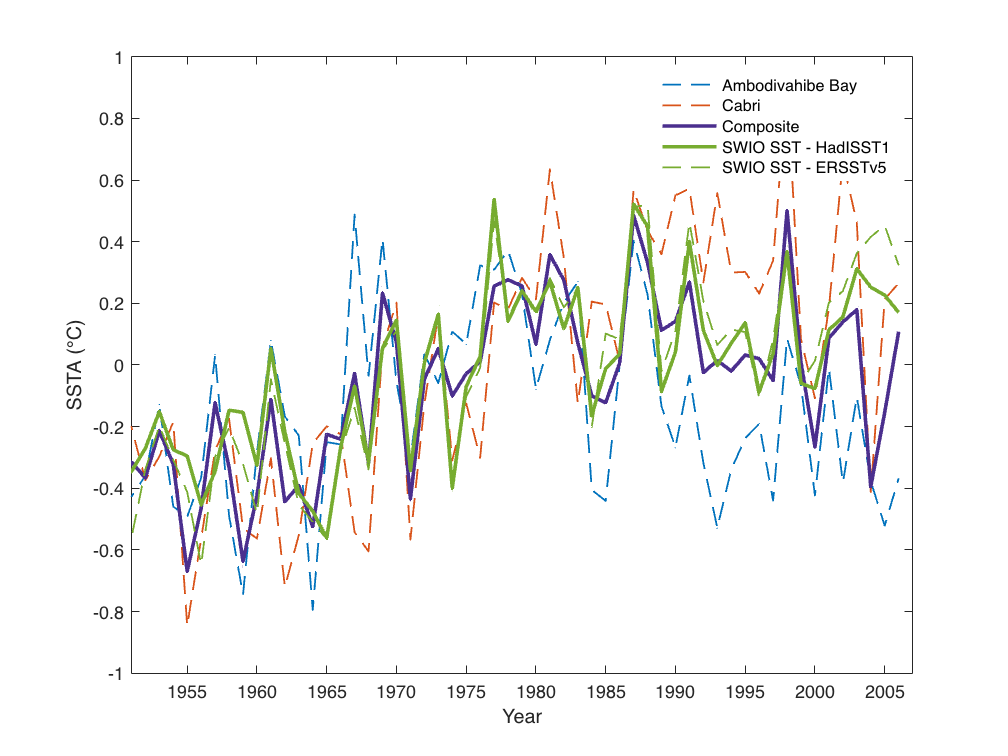

Cabri = readtable('AM_SWIO.xlsx','sheet','Cabri');
composite_monthly_SrCa = (Cabri.Cabri + SrCaA)/2;
composite_monthly_SSTA = composite_monthly_SrCa/-0.084;
monthlyCabriA = Cabri.Cabri/-0.084;
SWIOSST = readtable('AM_SWIO.xlsx','sheet','SST');

gap = (4:12:4024)';
yr = (1672:2006)';

ASSTAcomposite = zeros(size(yr,1),1);
for i=1:size(yr,1);
    t=composite_monthly_SSTA(gap(i):(gap(i+1)-1));
    ASSTAcomposite (i) = mean(t,'omitnan');
i=i+1;
end

ACabri = zeros(size(yr,1),1);
for i=1:size(yr,1);
    t=monthlyCabriA (gap(i):(gap(i+1)-1));
    ACabri(i) = mean(t,'omitnan');
i=i+1;
end

ERSSTv5_SWIO = zeros(size(yr,1),1);
for i=1:size(yr,1);
    t=SWIOSST.ERSSTv5(gap(i):(gap(i+1)-1));
    ERSSTv5_SWIO (i) = mean(t,'omitnan');
i=i+1;
end

HadI1_SWIO = zeros(size(yr,1),1);
for i=1:size(yr,1);
    t=SWIOSST.HadISST1(gap(i):(gap(i+1)-1));
    HadI1_SWIO (i) = mean(t,'omitnan');
i=i+1;
end

clf('reset')

hold on
plot(yr,ASSTA,'--','color',[0 0.4470 0.7410],'LineWidth',1)
plot(yr,ACabri,'--','color',[0.8500 0.3250 0.0980],'LineWidth',1)
plot(yr,ASSTAcomposite,'-','color',[0.2940 0.1840 0.5560],'LineWidth',2)
set(gca,'xlim',[1951 2007])
plot(yr, HadI1_SWIO,'-','color',[0.4660 0.6740 0.1880],'LineWidth',2)
plot(yr, ERSSTv5_SWIO,'--','color',[0.4660 0.6740 0.1880],'LineWidth',1)
box on
lg = legend('Ambodivahibe Bay','Cabri','Composite','SWIO SST - HadISST1','SWIO SST - ERSSTv5');
set(lg,'box','off')
xlabel('Year')
ylabel('SSTA (°C)')

fitlm(yr(280:end), ASSTAcomposite(280:end))

ans = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate        SE         tStat       pValue  
                   _________    _________    _______    __________

    (Intercept)      -18.646       3.7461    -4.9775     6.941e-06
    x1             0.0093927    0.0018934     4.9609    7.3617e-06


Number of observations: 56, Error degrees of freedom: 54
Root Mean Squared Error: 0.229
R-squared: 0.313,  Adjusted R-Squared: 0.3
F-statistic vs. constant model: 24.6, p-value = 7.36e-06

0.0093927*54 

ans = 0.5072

0.0018934*54

ans = 0.1022


fitlm(yr(280:end), HadI1_SWIO(280:end))

ans = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE        tStat       pValue  
                   ________    _________    ______    __________

    (Intercept)      -20.34       3.3448    -6.081    1.2644e-07
    x1             0.010273    0.0016905    6.0769    1.2835e-07


Number of observations: 56, Error degrees of freedom: 54
Root Mean Squared Error: 0.204
R-squared: 0.406,  Adjusted R-Squared: 0.395
F-statistic vs. constant model: 36.9, p-value = 1.28e-07

fitlm(yr(280:end), ASSTAcomposite(280:end))

ans = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate        SE         tStat       pValue  
                   _________    _________    _______    __________

    (Intercept)      -18.646       3.7461    -4.9775     6.941e-06
    x1             0.0093927    0.0018934     4.9609    7.3617e-06


Number of observations: 56, Error degrees of freedom: 54
Root Mean Squared Error: 0.229
R-squared: 0.313,  Adjusted R-Squared: 0.3
F-statistic vs. constant model: 24.6, p-value = 7.36e-06

0.010273*54 

ans = 0.5547

0.0016905*54

ans = 0.0913

SeasonSST= readtable("Seasonality.xlsx",'Sheet','SST_61_90');
sBM_SST = vertcat(SeasonSST.BMl,flipud(SeasonSST.BMu));
sHadISST1 = vertcat(SeasonSST.HadISST1l,flipud(SeasonSST.HadISST1u));
sERSSTv5 = vertcat(SeasonSST.ERSSTv5l,flipud(SeasonSST.ERSSTv5u));
seasonSSTMon = vertcat(SeasonSST.Mon,flipud(SeasonSST.Mon));
 clf
subplot(1,3,1)
hold on 
patch(seasonSSTMon,sBM_SST,[0.82 0.29 0.36],'Edgecolor','none','Facealpha',0.2)
patch(seasonSSTMon,sHadISST1- mean(TSST.HadISST,'omitnan'),[0.25, 0.53, 0.77],'Edgecolor','none','Facealpha',0.4)
patch(seasonSSTMon,sERSSTv5 - mean(TSST.ERSSTv5,'omitnan'),[0.4940, 0.1840, 0.5560],'Edgecolor','none','Facealpha',0.2)
plot(SeasonSST.Mon,SeasonSST.BM,'color',[0.82 0.29 0.36],'LineWidth',1,'Marker','.');
plot(SeasonSST.Mon,SeasonSST.HadISST1- mean(TSST.HadISST,'omitnan'),'color',[0.25, 0.53, 0.77],'LineWidth',1,'Marker','.');
plot(SeasonSST.Mon,SeasonSST.ERSSTv5 - mean(TSST.ERSSTv5,'omitnan'),'color',[0.4940, 0.1840, 0.5560],'LineWidth',1,'Marker','.');
legend('','','','Coral SST','HadISST1 SST','ERSSTv5 SST');
ylabel('SST (°C)')
xticks(1:2:24)
xticklabels({'Jan','Mar','May','Jul','Sep','Nov','Jan','Mar','May','Jul','Sep','Nov',})
xlabel('Mon')
box on
set(legend,'box','off')
subplot(1,3,[2 3])
hold on
plot(MC.Date,coralSST_centred,'linewidth',1,'color',[0.82 0.29 0.36])
patch(errordate,errSST_MC90,[0.82 0.29 0.36],'Edgecolor','none','Facealpha',0.3)
patch(errordate,errSST_MC68,[0.82 0.29 0.36],'Edgecolor','none','Facealpha',0.5)
plot(TSST.Date,ERSSTv5_centred,'linewidth',1,'color',[0.25, 0.53, 0.77])
plot(TSST.Date,HadISST_centred,'linewidth',1,'color',[0.4940, 0.1840, 0.5560])
set(gca,'xlim',[1961 1990])
ylabel('SST (°C)')
lg = legend('Coral SST','95% CI','68% CI','HadISST1 SST','ERSSTv5 SST','location','northeast');
set(lg,'box','off','Location','best')
box on 
xlabel('Year')

% MOVCORR Moving Pearson product-moment correlation coefficient r. This is
% basically a wrapper to MOVSUM and the low-memory overhead computation of r.
% See second formula in 
%   https://en.wikipedia.org/wiki/Pearson_correlation_coefficient#For_a_sample
%
% @Synopsis
%   r = MOVCORR(x, y, k) computes r for x and y over a centered window specified
%   by k.
%
%   MOVCORR(x, y, k, missing) specifies how to treats NaNs.
%
%   MOVSUM(...,'Endpoints',endpoints) controls how the start/end of the vectors
%   are handled.
%
%   [r, p] = MOVSUM(...) also returns the p-values for each computed r.
%
%   [r, p] = MOVSUM(...,'Tail',tail) controls what kind of hypothesis test is
%   used to compute the p-values.
%
% @Input
%   x, y (required)
%     m x 1 column vectors with the data to correlate.
%
%   k (required)
%      Positive integer scalar with the window size or 1x2 array of non-negative
%      integer scalars [nB, nF] with backward & forward samples for the window.
%      If k is a scalar and is even, the window is centered on the current &
%      previous sample, e.g. ranges from i-k/2 to i+k/2-1. If k is a vector the
%      window ranges from i-nB to i+nF.
%
%   missing (optional)
%     Flag of what to do with missing values. Either 'includenan' or 'omitnan'.
%     For 'omitnan' the r values are computed pairwise, resembling the behavior
%     of CORR(...,'Rows','pairwise') - but of course much faster.
%     DEFAULT: 'includenan'
%
%   'Endpoints',endpoints (Name/value)
%     Specifies how to handle the start/end of the vectors. Either a numeric or
%     logical scalar or 'shrink', 'fill' or 'discard'. Be aware that using
%     arbitrary numeric values does not really make sense in this setting (as
%     the correlation coefficient is bound between -1 and 1). Moreover, when
%     using numeric/logical endpoints, the according p-values are set to NaN.
%     This result in unexpected NaNs: If missing=='omitnan' and endpoints is
%     numeric, then p will contain NaNs at the endpoints, despite r beeing
%     finite.
%     DEFAULT: 'shrink'
%
%   'Tail',tail (Name/value)
%     Specifies the hypothesis with which the p-values are computed. Either
%     'both', 'left' or 'right'. See CORR for more details.
%     DEFAULT: 'both'
%
%   'MinN',nMin (Name/value)
%     Positive integer scalar with the minimum number of non-NaN values in a
%     local window required for computation of r. If a window does not have the
%     required number of values, r is not computed (e.g. set to NaN). 'MinN' has
%     to be equal or smaller than the window length specified by k. This
%     option is ignored if missing=='includenan'. Setting 'MinN' > 1 when using 
%     'Endpoints'=='shrink' may cause the values at the borders to be NaN,
%     despite the 'shrink' option.
%     DEFAULT: 1 (always compute r)
%
% @Output
%   r
%     m x 1 column vector with the local Pearson correlation coefficients for
%     each mutual sample in x and y.
%
%   p
%     m x 1 column vector with the p-values for the local Pearson correlation
%     coefficients.
%
%   n
%     The number of non-NaN values in each local window. If
%     missing=='includenan', this is a scalar equal to the window size. If
%     missing=='omitnan', this is an m x 1 column vector with the number of
%     non-NaN elements in each local window. This can be used to compute the
%     degrees-of-freedom for partial correlations.
%
% @Remarks
%   - For more detailed info on the inputs & syntax see MOVSUM.
%
% @Dependencies
%   none
%
% See also CORR, MOVSUM
%
% ML-FEX ID:65342
%
% @Changelog
%   2017-12-07 (DJM): 
%     - [RELEASE] Golden.
%     - [MOD] Computation of r with NaNs + 'omitnan' now gives same results as
%       CORR(...,'Rows','pairwise').
%   2017-12-11 (DJM): 
%     - [ADD] Name-value input 'Tail' and according p-value output.
%     - [MOD] Now uses INPUTPARSER. Changes error messages for invalid inputs.
%     - [FIX] Erroneous window size computation when using k = [nB, nF].
%     - [FIX] Complex output when using numeric endpoints.
%   2017-12-12 (DJM): 
%     - [ADD] Output n.
%   2017-12-14 (DJM): 
%     - [ADD] Name-value input 'MinN'.
%     - [MOD] Now returns NaN for zero-variances, to be consistent with CORR.
%

function [r, p, n] = movcorr(x, y, k, varargin)
%% Parse inputs
[x, y, k, missing, endpoints, tail, nMin, n] ...
    = parseInputs(x, y, k, varargin);
isNumericEndpoints = ~ischar(endpoints);
if isNumericEndpoints
	% With numeric/logical endpoints, we set the method to 'fill' and set the
	% values in the end, to avoid problems when using MOVSUM on x & x^2.
	endpointVals = endpoints;
	endpoints    = 'fill';
end
%% Assemble lambda function for MOVSUM
movingSum = @(v) movsum(v, k, missing, 'Endpoints',endpoints);
%% Compute sums
sumX = movingSum(x);
sumY = movingSum(y);
%% Compute r
% Use SQRT in denominator on x & y separately to avoid under/overflow.
r = (n .* movingSum(x.*y) - sumX.*sumY) ...
 ./ (sqrt(n .* movingSum(x.^2) - sumX.^2) .* sqrt(n .* movingSum(y.^2) - sumY.^2));
%% Handle values > +/-1
% Use same method as CORR to be consistent. This will cause INFs to be NaN...
% which might be argued upon.
isExceeding = abs(r) > 1;
r(isExceeding) = r(isExceeding) ./ abs(r(isExceeding));
%% Remove invalid windows
if strcmp(missing, 'omitnan')
	r(n < nMin) = NaN; % n is vector if missing=='omitnan'.
end
%% Compute p-values
if nargout() > 1
	p = computePvalues(r, n, tail);
end
%% Handle endpoints
if isNumericEndpoints
	ids = [1 : k(1), length(r) - k(2) + 1 : length(r)];
	r(ids) = endpointVals;
	p(ids) = NaN;
end
end % MAINFUNCTION
%% SUBFUNCTION: parseInputs
% PARSEINPUTS Parses the inputs to the main function.
%
% @Input
%   x,y,k (required)
%     Required main function inputs.
%
%   varArgIn (required)
%     Optional main function inputs (VARARGIN).
%
% @Output
%   x,y,k
%     Required main function inputs.
%
%   missing
%     Optional main function input.
%
%   endpoints,tail,nMin
%     Name-value main function inputs.
%
%   n
%     Window length (based on k). If isAnyNan==true this is a mx1 vector with
%     the local window sizes for finite-values.
%
function [x, y, k, missing, endpoints, tail, nMin, n] = parseInputs(x, y, k,...
                                                                    varArgIn)
%% >SUB: Init
% Valid enumeration vals. First is used as default.
VALID_MISS    = {'includenan', 'omitnan'};
VALID_ENDPNTS = {'shrink', 'discard', 'fill'};
VALID_TAILS   = {'both', 'left', 'right'};
% Error messages - partly resembles errors from MOVSUM.
ERR_BASE_ID = 'DJM:IOFailure';
ERR_MSG_X_Y_DIM         = '''x'' and ''y'' have to be of equal size.';
ERR_MSG_K_INVALID       = '''k'' must be a finite scalar positive integer or 2-element vector of finite nonnegative integers.';
ERR_MSG_MISS_INVALID    = '''missing'' value must be ''omitnan'' or ''includenan''.';
ERR_MSG_ENDPNTS_INVALID = '''Endpoints'' value must be ''shrink'', ''discard'', ''fill'', or a numeric or logical scalar.';
ERR_MSG_TAIL_INVALID    = '''Tail'' value must be ''both'', ''left'' or ''right''.';
ERR_MSG_MIN_N_INVALID   = '''MinN'' has to be equal or smaller than the window length given by ''k''.';
ERR_MSG_MIN_N_IGNORED   = '''MinN'' is ignored with option ''includenan''.';
ERR_MSG_MIN_N_SHRINKED  = '''MinN'' may cause unexpected NaNs at the borders with option ''shrink''.';
%% >SUB:  Create INPUTPARSER
IP = inputParser();
IP.StructExpand  = true;
IP.KeepUnmatched = false;
%% >SUB: Set up validation functions
validateNumCol          = @(v)validateattributes(v,{'numeric'},{'column'});
validateNumScaFinIntPos = @(v)validateattributes(v,{'numeric'},{'scalar','finite','integer','positive'});
validateNumVecFinIntNN  = @(v)validateattributes(v,{'numeric'},{'vector','finite','integer','nonnegative'});
validateCharOrNumRow    = @(v)validateattributes(v,{'char','numeric','logical'},{'row'});
validateCharRow         = @(v)validateattributes(v,{'char'},{'scalartext'});
%% >SUB: Define inputs
IP.addRequired( 'x'        , validateNumCol);
IP.addRequired( 'y'        , validateNumCol);
IP.addRequired( 'k'        , validateNumVecFinIntNN);
IP.addParameter('Endpoints', VALID_ENDPNTS{1}, validateCharOrNumRow);
IP.addParameter('Tail'     , VALID_TAILS{1}  , validateCharRow);
IP.addParameter('MinN'     , 1               , validateNumScaFinIntPos);
%% >SUB: Parse 'missing' if given
% This is an optional input which can be ommitted and thus cannot be handled by
% INPUTPARSER.
isDefault = isempty(varArgIn) || ~ischar(varArgIn{1}) ...
         || ismember(varArgIn{1}, {'Endpoints', 'Tail', 'MinN'});
if isDefault
	missing = VALID_MISS{1}; % Use default.
else
	missing = varArgIn{1};
	varArgIn(1) = [];
	errId = [ERR_BASE_ID ':MissingInvalid'];
	assert(ismember(missing, VALID_MISS), errId, ERR_MSG_MISS_INVALID);
end
%% >SUB: Parse & assign
IP.parse(x, y, k, varArgIn{:});
endpoints = IP.Results.Endpoints;
tail      = IP.Results.Tail;
nMin      = IP.Results.MinN;
%% >SUB: Check k
% Convert scalar k to [nB,nF] notation.
if isscalar(k)
	k = floor(k / 2) + [0, -double(mod(k, 2) == 0)];
end
errId = [ERR_BASE_ID ':KInvalid'];
assert(numel(k) == 2 && all(k >= 0), errId, ERR_MSG_K_INVALID);
winSize = sum(k) + 1; % nB + nF + current sample
%% >SUB: Check size of x & y
errId = [ERR_BASE_ID ':XYInvalid'];
assert(isequal(size(x), size(y)), errId, ERR_MSG_X_Y_DIM);
%% >SUB: Check NaNs in x & y
if strcmp(missing, 'includenan')
    n = winSize;
else
	isNanX = isnan(x);
	isNanY = isnan(y);
	isNanXorY = isNanX | isNanY;
	if any(isNanXorY)
		% Set NaNs mutually in both vectors.
		x(isNanY) = NaN;
		y(isNanX) = NaN;
		n = movsum(~isNanXorY, k);
	end
end
%% >SUB: Check endpoints
errId = [ERR_BASE_ID ':EndpointsInvalid'];
if ischar(endpoints)
	isValid = ismember(endpoints,VALID_ENDPNTS);
else % Numeric or logical
	isValid = isscalar(endpoints);
end
assert(isValid, errId, ERR_MSG_ENDPNTS_INVALID);
   
%% >SUB: Check tail
errId = [ERR_BASE_ID ':TailInvalid'];
assert(ismember(tail, VALID_TAILS), errId, ERR_MSG_TAIL_INVALID);
%% >SUB: Check MinN
errId = [ERR_BASE_ID ':MinNInvalid'];
assert(nMin <= winSize, errId, ERR_MSG_MIN_N_INVALID);
if ~ismember('MinN', IP.UsingDefaults)
    if strcmp(missing, 'includenan')
        errId = [ERR_BASE_ID ':MinNIgnored'];
        warning(errId, ERR_MSG_MIN_N_IGNORED);
    elseif nMin > 1 && strcmp(endpoints,'shrink') % & missing==omitnan
        errId = [ERR_BASE_ID ':MinNCausingNaNs'];
        warning(errId, ERR_MSG_MIN_N_SHRINKED);
    end
end
end % PARSEINPUTS
%% SUBFUNCTION: computePvalues
% COMPUTEPVALUES Computes the p-values for the r's.
%
% @Input
%   r, n, tail (required)
%     Main function variables.
%
% @Output
%   p
%     Array same size as r with p-values.
%
function p = computePvalues(r, n, tail)
%% >SUB: Compute t-statistics
% t-statistic for r from Rudolf2008 - Biostatistik, p.213 eq. 7.9.
dof = n - 2; % Degrees-of-freedom.
t   = r .* sqrt(dof ./ (1 - r.^2));
%% >SUB: Compute p-values
if strcmp(tail, 'both')
	% Two-sided.
	p = 2 * tcdf(-abs(t), dof); % == 2 * (1 - tcdf(-abs(t), dof))
else
	% One-sided: left or right.
	if strcmp(tail, 'right')
		t = -t; % 1 - tcdf(t, dof) == tcdf(-t, dof)
	end
	p = tcdf(t, dof);
end
end % COMPUTEPVALUES